C_propuesto_2 = ((s+1)^3)/(s*s*(s+1000));
rlocus(C_propuesto_2*Planta)
bode(C_propuesto_2*Planta, optionss)
bode(C_propuesto_2*Planta*db2mag(115), optionss)

% %calculo de Ts
% T = [0.1 0.22 0.01 0.0075 0.05 0.04 0.03 0.02 0.001];
% 
% 
% figure()
% bode(C_propuesto_2*Planta*db2mag(115), optionss, 'black');
% grid on
% hold on
% for i=1:length(T)
%     T(i)
%     Pad=(1-T(i)/4*s)/(1+T(i)/4*s);
%     bode(C_propuesto_2*Planta*db2mag(115)*Pad, optionss)
% end
% 
% legend('L', '0.1', '0.22',' 0.01 ', '0.0075','0.05 ','0.04 ','0.03 ','0.02 ','0.001')
% hold off

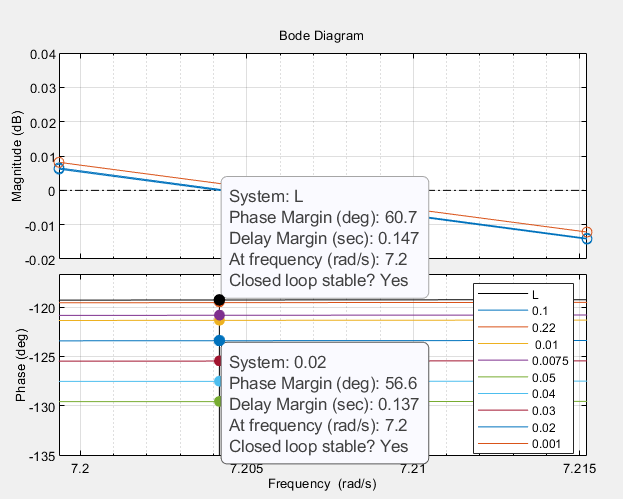

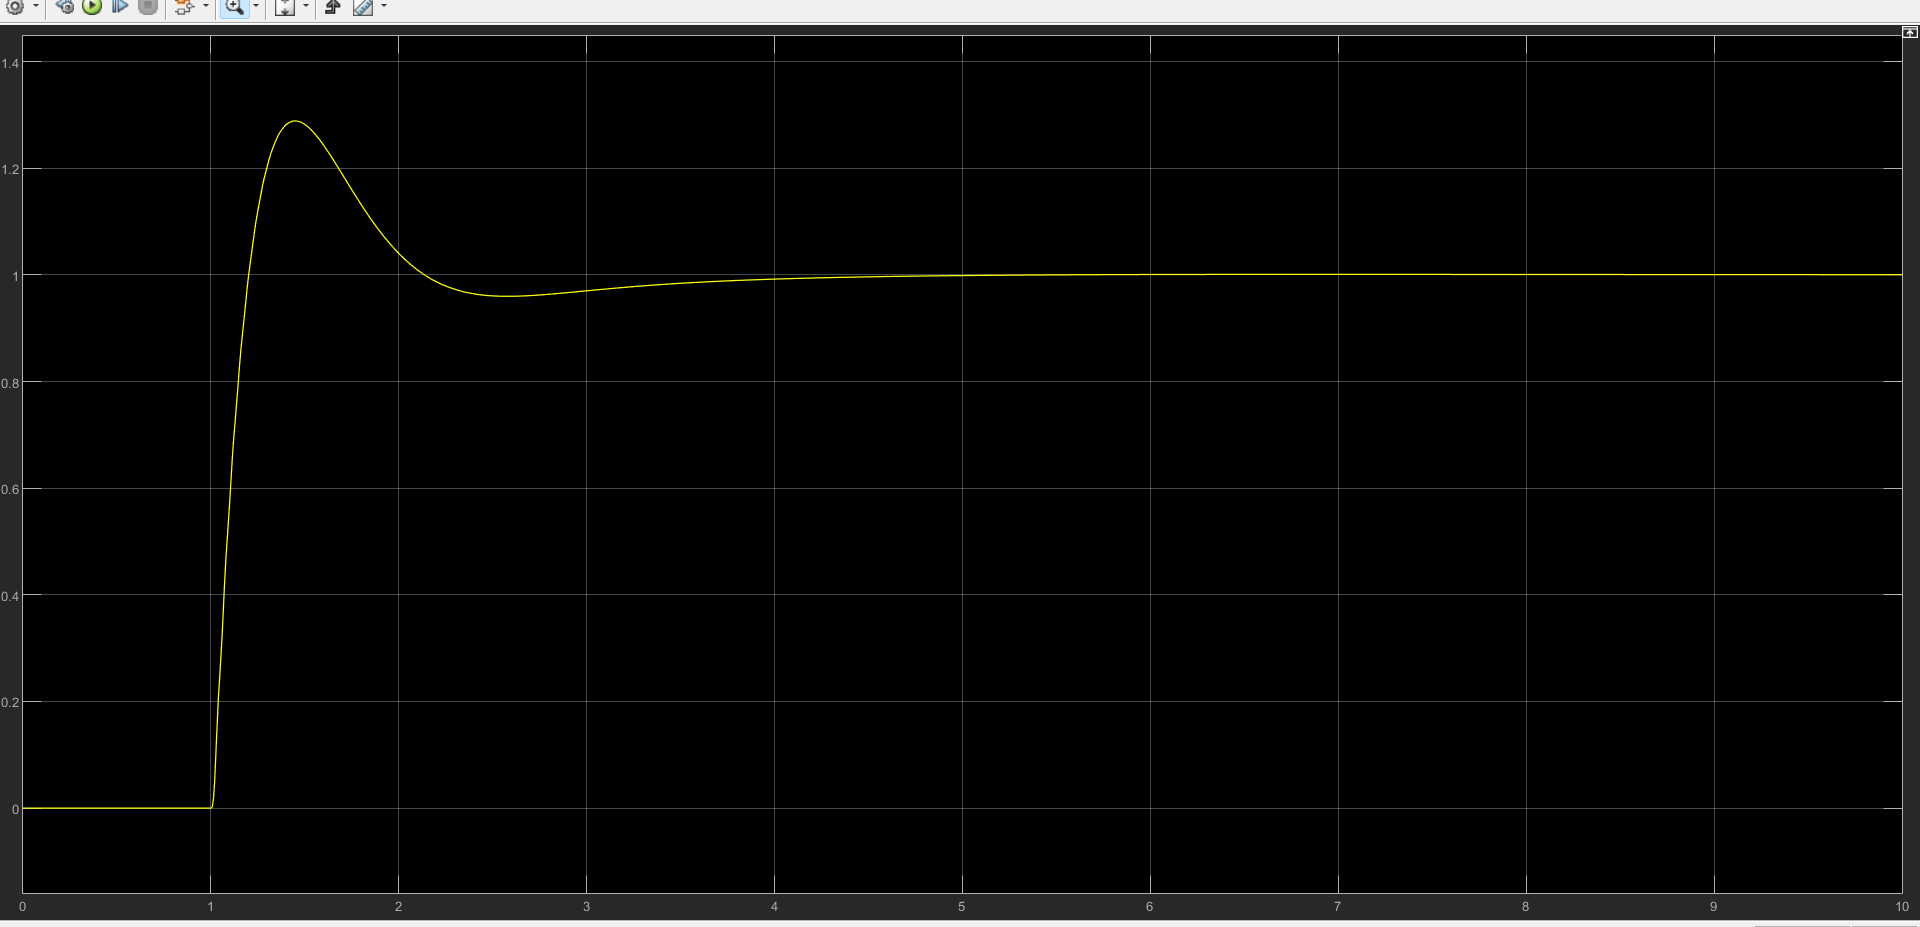

pade_2 = (1-0.02/4*s)/(1+0.02/4*s);
L = C_propuesto_2*Planta*db2mag(115)*pade_2;
bode(L, optionss)
C_d_2=c2d(C_propuesto_2*db2mag(115), 0.02, 'tustin')